# APT raw data cropping

## loading of data

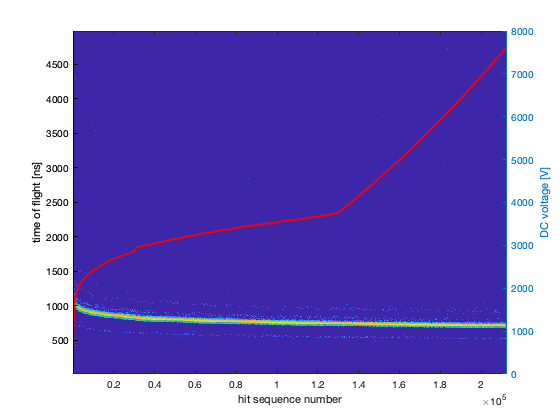

%[pos, instrument, raw] = oxcartHdf5ToPos();

%plotting data history
historyFig = figure("Name","experiment history");
historyAx = axes(historyFig);
MAXTOF = 5000; %maximum time of flight that makes sense
HISTORYPIX = 1024; %number of pixels in the hit sequence tof image
TOFPIX = 512; % number of vertical pixels for tof image

numAtom = length(pos.detx);

tofCrop = [(1:numAtom)' pos.tof]; 
tofCrop = tofCrop(tofCrop(:,2) < MAXTOF,:);

[tofImage, tofImageCenters] = hist3(double(tofCrop),[HISTORYPIX,TOFPIX]);
tofImage = tofImage';
tofImage = log(tofImage); % if weak peaks are to be imaged
im = imagesc(tofImage,'XData',tofImageCenters{1},'YData',tofImageCenters{2});
historyAx.YDir = "normal";

% plotting voltage history
yyaxis right
p = plot(pos.VDC,'r');
p.LineWidth = 2;
ylabel 'DC voltage [V]'

% image formatting
yyaxis left
ylabel 'time of flight [ns]'
xlabel 'hit sequence number'

## cropping experiment history

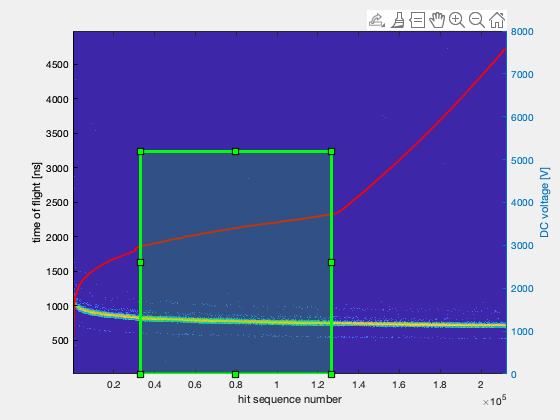

tofRoi = drawrectangle(historyAx,"Color",[0 1 0]);

minIdx = tofRoi.Vertices(1,1)

minIdx = 3.3087e+04

maxIdx = tofRoi.Vertices(3,1)

maxIdx = 1.2671e+05

pos(pos.ionIdx<minIdx,:) = [];
pos(pos.ionIdx>maxIdx,:) = [];

## cropping detector area

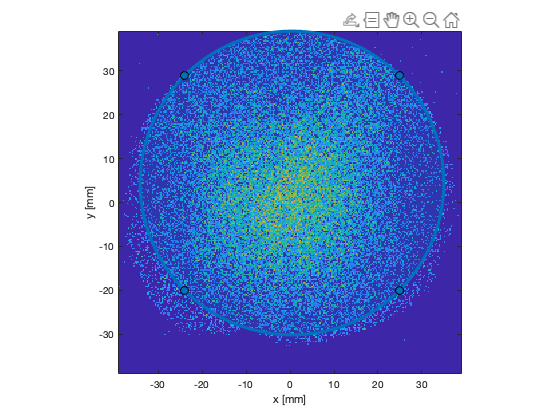

FDMRESOLUTION = 256; % pixels for FDM
FDMfig = figure("Name","field desorption map");
FDMax = axes(FDMfig);

[FDM, FDMcenters] = hist3([double(pos.detx), double(pos.dety)],[FDMRESOLUTION,FDMRESOLUTION]);
FDM = log(FDM);
FDMim = imagesc(FDM,'XData',FDMcenters{1},'YData',FDMcenters{2});
FDMax.YDir = "normal";

axis equal;
axis tight
xlabel 'x [mm]'
ylabel 'y [mm]'
detRoi = drawcircle(FDMax);

% select detector region of interest

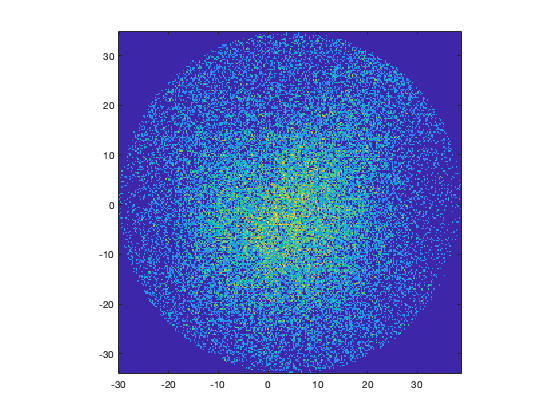

detectorDist = sqrt((double(pos.detx) - detRoi.Center(2)).^2 + (double(pos.dety) - detRoi.Center(1)).^2);
in = detectorDist < detRoi.Radius;
numHits = height(pos);

pos2 = pos(in,:);

[FDM, FDMcenters] = hist3([double(pos2.detx), double(pos2.dety)],[FDMRESOLUTION,FDMRESOLUTION]);
FDM = log(FDM);
FDMim = imagesc(FDM,'XData',FDMcenters{1},'YData',FDMcenters{2});
FDMax.YDir = "normal";

axis equal;
axis tight


tofCropLossPct = (1 - height(pos2)/height(pos))*100

tofCropLossPct = 6.8051

pos = pos2;
clear pos2;